# Time evolution for the NLS equation on a dumbbell graph

Evolves the basic heat equation through time.

## Set up the graph structure and coordinates of the problem

By default, the discretization type is uniform but you must choose it to be Chebyshev for the time evolution. You can also set other properties such as the number of discretization points per edge.

tag='dumbbell';
Phi = quantumGraphFromTemplate(tag,'discretization','Chebyshev','nX',32);

## Define the function

Defining the non-linear Schrodinger equation on Phi.

fcns = getGraphFcns(Phi);
lambda = 1;
f =@(t,z) fcns.f(z,lambda);

## Time evolution

The first step for our time evolution is developing a good initial condition. We will use a solution to the stationary problem

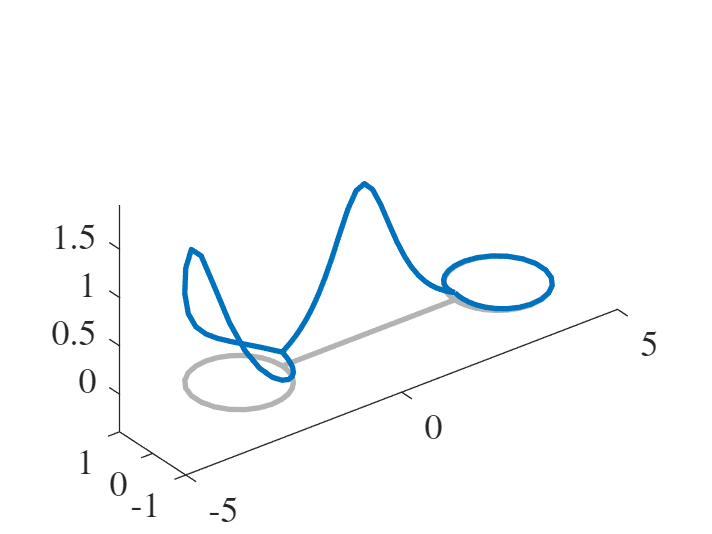

u0 = load(fullfile('data\dumbbell\001\branch006\PhiColumn.010'));
Phi.plot(u0)

In addition to the initial condition, we need the step size, how long the program should run till and the scheme type you desire. Right now, we have 2nd, 4th and 8th order schemes. For this example, I used a modified version of the DoPri-8 scheme.

tend = 1;
deltat = 1e-04;
[u,t] = Phi.timeEvolveDAE(f,u0,deltat,tend,8);

## Plotting the solution

Plotting every piece of information is too much. We'll only plot every 1000th data point.

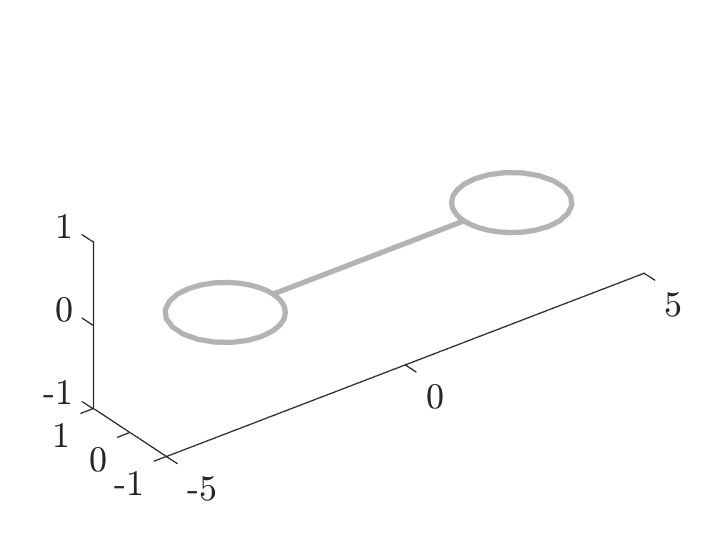

Error using matlab.graphics.axis.Axes/set
Value must be a 1x2 vector of numeric type in which the second element is greater than the first element or is Inf.

Error in quantumGraph/plotOnGraph2D (line 39)
set(gca,'ZLim',[(yMin-yRange/4), (yMax +yRange/4)])

Error in quantumGraph/plotOnGraph (<a hre

scale = 1/(100*deltat);
for i=1:size(u,2)/scale
    clf
    Phi.plot(abs(u(:,scale*i)).^2)
    axis([-4 4 -1.5 1.5 -.5 3])
    daspect([1 1 1])
    title(['$t=$',num2str(t(scale*i))])
    zlabel('$u^2$')
    pause(.0000000001)
end

## Error Analysis

????